clear all;
%close all;

%addpath('utility_functions');

 
hexa_file_name = 'D:\PROJECTS\PIXL\analysis\AutonomousSafetyAssessment\safety_assesment\PIXL_SafetySurvey\2022_11_23_15_10_06\2022_11_23_14_58_10.txt';
sli_file_path = 'D:\PROJECTS\PIXL\analysis\AutonomousSafetyAssessment\safety_assesment\PIXL_SafetySurvey\2022_11_23_15_10_06\download\';
% hexa_file_name = 'D:\PROJECTS\PIXL\analysis\AutonomousSafetyAssessment\safety_assesment\PIXL_SafetySurvey\2022_12_05_15_50_04\2022_12_05_15_35_57.txt';
% sli_file_path = 'D:\PROJECTS\PIXL\analysis\AutonomousSafetyAssessment\safety_assesment\PIXL_SafetySurvey\2022_12_05_15_50_04\download\';

%altered pivot point def
hexa_file_name = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\2022_12_06_13_41_24\2022_12_06_13_29_22.txt';
sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\2022_12_06_13_41_24\download\';

 
file = fileread(hexa_file_name);

hexa_string_all(1,:) = strfind(file,"X: ");
hexa_string_all(2,:) = strfind(file,", Y");
hexa_string_all(3,:) = strfind(file,"Y: ");
hexa_string_all(4,:) = strfind(file,", Z");
hexa_string_all(5,:) = strfind(file,"Z: ");
hexa_string_all(6,:) = strfind(file,", U");
hexa_string_all(7,:) = strfind(file,"U: ");
hexa_string_all(8,:) = strfind(file,", V");
hexa_string_all(9,:) = strfind(file,"V: ");
hexa_string_all(10,:) = strfind(file,", W");
hexa_string_all(11,:) = strfind(file,"W: ");

for i=1:size(hexa_string_all,1)
    hexa_string(i,:) = hexa_string_all(i,2:2:end);
end

hexa_string(12,:) = strfind(file,", T");


for j=1:size(hexa_string,2)
    for i=1:size(hexa_string,1)/2
        hexa_pos(i,j) = double(string(file(hexa_string(i*2-1,j)+3:hexa_string(i*2,j)-1)));
    end
end
hexa_pos(1,:) = hexa_pos(1,:)*10^3;
hexa_pos(2,:) = hexa_pos(2,:)*10^3;
hexa_pos(3,:) = hexa_pos(3,:)*10^3;
hexa_pos(4,:) = hexa_pos(4,:);
hexa_pos(5,:) = hexa_pos(5,:);

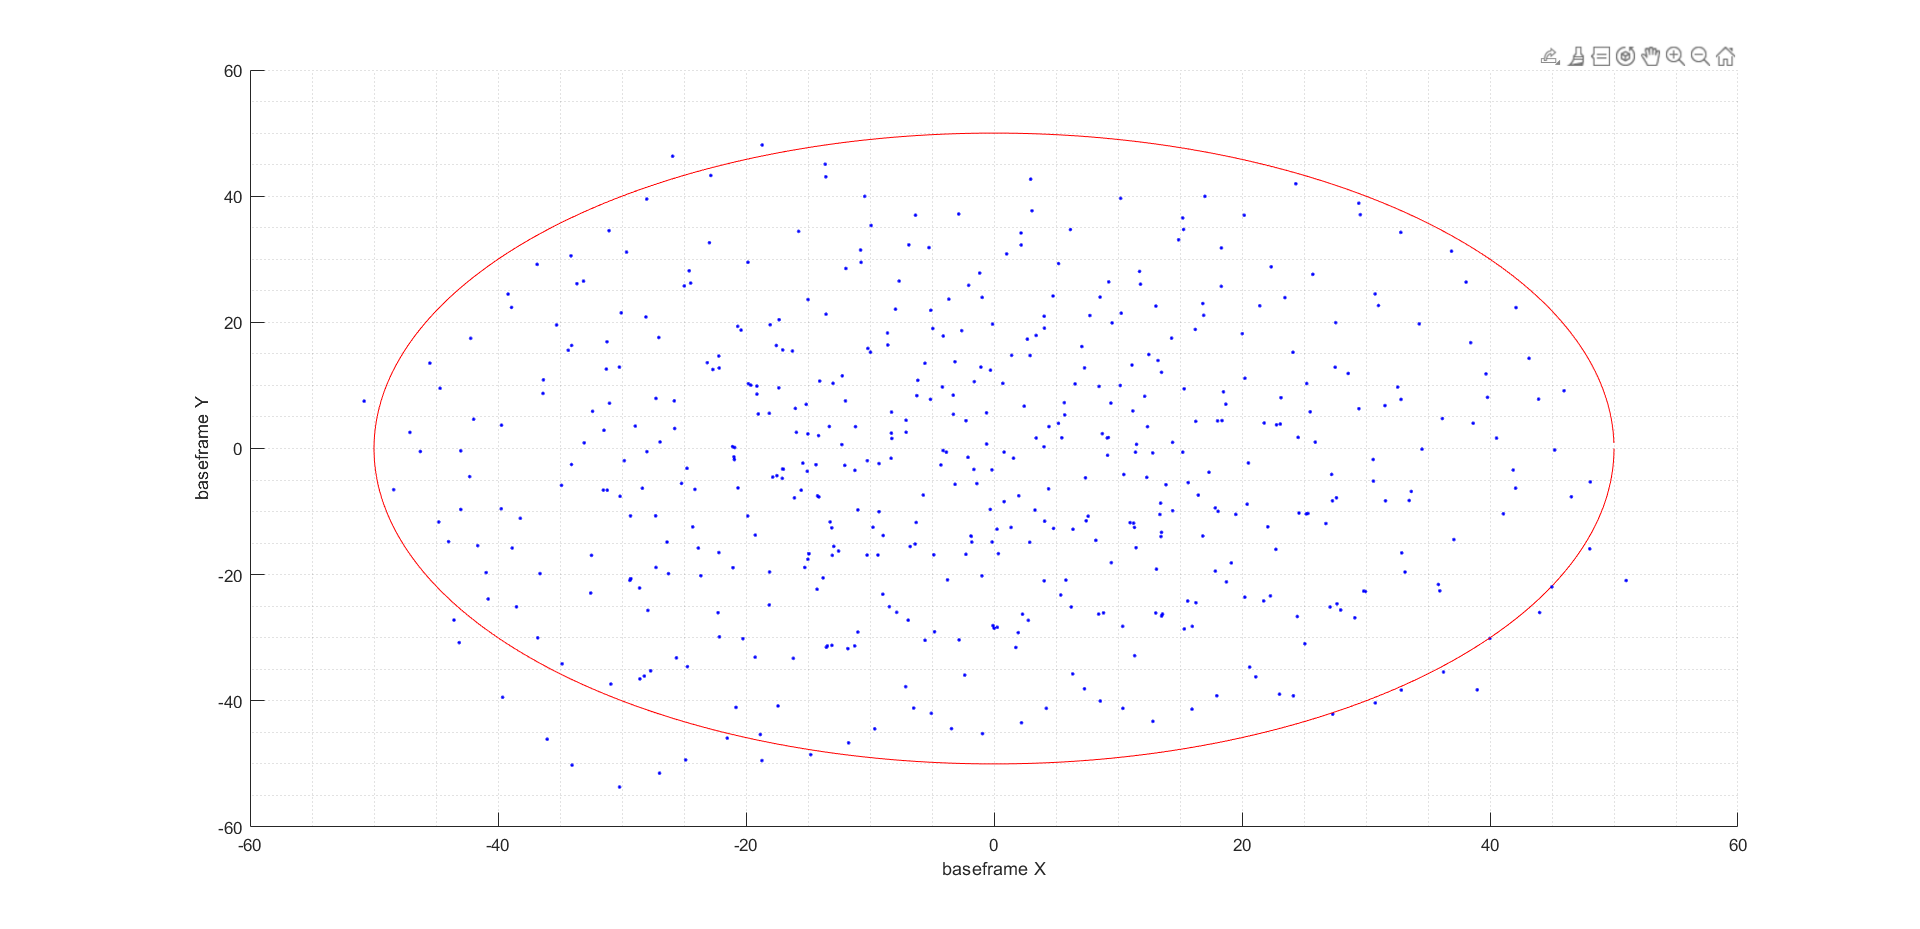


 
%hexa_pos = [1e3.*pos_xy, sortedCoords];
 
sli_files = dir([sli_file_path '*.unk']);

% figure(100)
for i=1:length(sli_files)
    [h,sli(i,:),m] = readAscImage([sli_file_path sli_files(i).name]);  
    
%     clf;
%     plot(sli(i,:).sliData.cen(:,1), sli(i,:).sliData.cen(:,2), '.')
%     axis ij
%     axis equal
%     axis([0 752 0 580])
%     waitforbuttonpress
end

%hexa_pos(:,1:length(sli_files)) = hexa_pos(:,size(hexa_pos,2)-length(sli_files)+1:end) ;
 
%Cam rotation
best_angle_x = 18.27;
best_angle_y = -0.38;
best_angle_z = 0.2700;

pivot_point = 190*10^3; %um %distance from pivot point to Target frame
c2x_y = 23*10^3;        %um
x2c_z = 22997;          %um
desired_distance = 30*10^3; %um

 
 
 
% Rotate and translate to "sensor frame"
for i=1:size(sli,1)
    temp = sli(i).sliData.Q'; 
    temp(4,:) = 1;
    sli_data_rot{i}.Q = temp;
    T = [0 c2x_y (pivot_point-desired_distance-x2c_z)]';
%     T = [0 c2x_y (pivot_point-x2c_z)]';
    R = createRotationMatrix(best_angle_z,best_angle_y,best_angle_x);
    P = [R T];
    sli_data_rot{i}.Q = P*sli_data_rot{i}.Q;
end

sli_data_hexa = sli_data_rot;

% Rotate and translate to "base frame"
for i=1:size(sli,1)
    sli_data_hexa{i}.Q(4,:) = 1;
    R_hex = createRotationMatrix(-hexa_pos(6,i),-hexa_pos(5,i),-hexa_pos(4,i));
    R_hex = createRotationMatrix(hexa_pos(6,i),hexa_pos(5,i),hexa_pos(4,i));
    T_hex = [hexa_pos(1:3,i)];
    P_hex = [R_hex' T_hex];
    sli_data_hexa_rot{i}.Q = P_hex * sli_data_hexa{i}.Q;

end

 
figure
clf
hold on;
for i=1:size(sli_data_hexa_rot,2)
%     plot3(sli_data_hexa_rot{i}.Q(1,:)/1000,sli_data_hexa_rot{i}.Q(2,:)/1000,sli_data_hexa_rot{i}.Q(3,:)/1000,'.','color',colors(i,:))
    plot3(sli_data_hexa_rot{i}.Q(1,:)/1000,sli_data_hexa_rot{i}.Q(2,:)/1000,sli_data_hexa_rot{i}.Q(3,:)/1000,'.b')
%     plot3(mean(sli_data_hexa_rot{i}.Q(1,:))/1000,mean(sli_data_hexa_rot{i}.Q(2,:))/1000,mean(sli_data_hexa_rot{i}.Q(3,:))/1000,'*','color',colors(i,:),'markersize',10)
waitforbuttonpress
end
grid minor;

hold on
circ_x = cosd(1:360);
circ_y = sind(1:360);
circ_r = 50;
plot3(circ_x*circ_r, circ_y*circ_r, mean(sli_data_hexa_rot{i}.Q(3,:)/1000)*ones(size(circ_x)), 'r')
%axis equal
% axis ij;
xlabel("baseframe X")
ylabel("baseframe Y")
zlabel("baseframe Z")


x = [];
y = [];
z = [];
for i=1:size(sli_data_hexa_rot,2)
    x = [x sli_data_hexa_rot{i}.Q(1,:)/1000];
    y = [y sli_data_hexa_rot{i}.Q(2,:)/1000];
    z = [z sli_data_hexa_rot{i}.Q(3,:)/1000];
end
tri = delaunay(x,y);
figure
trisurf(tri,x,y,z)
% axis equal
xlabel("baseframe X")
ylabel("baseframe Y")
zlabel("baseframe Z")
range(z)

ans = 3.6914

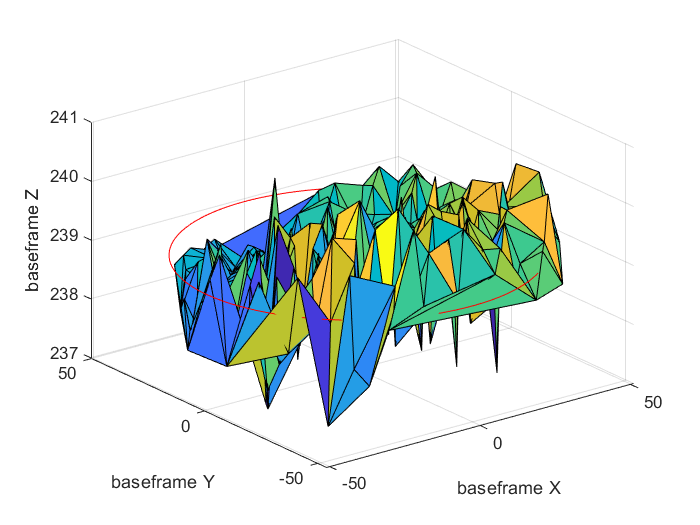

hold on
circ_x = cosd(1:360);
circ_y = sind(1:360);
circ_r = 50;
plot3(circ_x*circ_r, circ_y*circ_r, mean(z)*ones(size(circ_x)), 'r')

%axis equal
% surf(sli_data_hexa_rot{i}.Q(1,:)/1000,sli_data_hexa_rot{i}.Q(2,:)/1000,sli_data_hexa_rot{i}.Q(3,:)/1000)


hold off

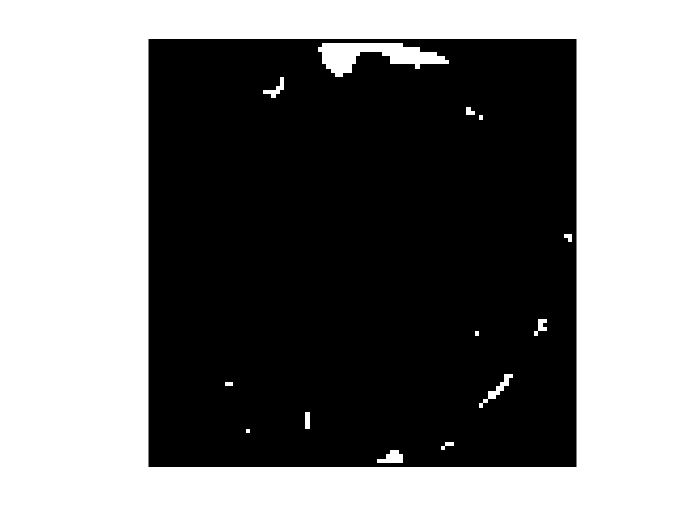

Docked figures do not support 'WindowState'.

Error in calculateArea (line 24)
    g.WindowState = 'maximized';

area_now = calculateArea(50, 5, 1, [x', y', z'], 1)